## PREPROCESADO

### Renombrar variables

nombres_variables = ["SepalLength", "SepalWidth", "PetalLength", "PetalWidth", "Species"];
iris.Properties.VariableNames = nombres_variables;

rng(385567); % Semilla para reproducibilidad

% head(iris)

### Realizar un shuffle pseudoaleatorio de las muestras

% Crear un índice aleatorio
idx = randperm(height(iris));  % height devuelve el número de filas

% Aplicar el índice para reorganizar las filas
iris_copy = iris(idx, :);

head(iris_copy)

    SepalLength    SepalWidth    PetalLength    PetalWidth        Species    
    ___________    __________    ___________    __________    _______________

        5.8           2.8            5.1           2.4        Iris-virginica 
        5.1           3.8            1.5           0.3        Iris-setosa    
        5.5           3.5            1.3           0.2        Iris-setosa    
        5.6             3            4.1           1.3        Iris-versicolor
        5.9           3.2            4.8           1.8        Iris-versicolor
        6.2           2.9            4.3           1.3        Iris-versicolor
        5.8           2.7            5.1           1.9        Iris-virginica 
        6.5           2.8            4.6           1.5        Iris-versicolor



### One Hot Encoding de las etiquetas

% Extraer las etiquetas de salida
outputs = iris_copy.Species;

% Obtener las clases únicas
classes = char(unique(outputs));  % Convierte de categórico a char array

% Aplicar one-hot encoding
onehotIris = onehotencode(outputs, 2, 'ClassNames', classes)

onehotIris =      0     0     1
     1     0     0
     1     0     0
     0     1     0
     0     1     0
     0     1     0
     0     0     1
     0     1     0
     1     0     0
     1     0     0


% Preparar las variables predictoras y etiquetas
X = iris_copy{:, 1:4}; % variables numéricas
Y = iris_copy{:, 5}; % etiquetas
T = array2table(onehotIris, 'VariableNames',{'IrisSetosaOHE','IrisVersicolorOHE','IrisVirginicaOHE'}) % etiquetas codificadas

T = 150×3 table
    IrisSetosaOHE    IrisVersicolorOHE    IrisVirginicaOHE
    _____________    _________________    ________________

          0                  0                   1        
          1                  0                   0        
          1                  0                   0        
          0                  1                   0        
          0                  1                   0        
          0                  1                   0        
          0                  0                   1        
          0                  1                   0        
          1                  0                   0        
          1                  0                   0        
          0                  1                   0        
          0                  0                   1        
          1                  0                   0     

## Entrenamiento de Red Neuronal

Se usó LOOCV como método de Cross Validation y 3 repeticiones. 

% =======================================================
% ==================== CONFIGURACIÓN ====================
% =======================================================
% Definir configuraciones de la red neuronal
numNeuronas = [5, 10, 15];  % número de neuronas en la capa oculta
algoritmosEntrenamiento = {'trainscg', 'trainlm'};  % algoritmos de entrenamiento (primer orden: gradiente conjugado escalado, 
                                                    %                              segundo orden: Levenberg-Marquardt)
number_reps = 3;  % número de repeticiones

% Generar combinaciones
[NEUR, ALG] = ndgrid(numNeuronas, 1:length(algoritmosEntrenamiento));
combinaciones = [NEUR(:), ALG(:)];
numCombinaciones = size(combinaciones, 1);

% Variables de entrada y salida
variablesContinuas = [1,2,3,4];
clasesUnicas = categories(categorical(Y));
NumClases = length(clasesUnicas);

% Inicializar almacenamiento
nnModels = cell(1, numCombinaciones, number_reps);
metricsNN = struct('Accuracy', zeros(1, numCombinaciones, number_reps), ...
                   'Precision', zeros(1, numCombinaciones, number_reps), ...
                   'Specificity', zeros(1, numCombinaciones, number_reps), ...
                   'Recall', zeros(1, numCombinaciones, number_reps), ...
                   'F1Score', zeros(1, numCombinaciones, number_reps));

metricsClassNN = struct();
metricsClassNN.Recall = zeros(numCombinaciones, NumClases, number_reps);
metricsClassNN.Precision = zeros(numCombinaciones, NumClases, number_reps);
metricsClassNN.Specificity = zeros(numCombinaciones, NumClases, number_reps);
metricsClassNN.Accuracy = zeros(numCombinaciones, NumClases, number_reps);
metricsClassNN.F1Score = zeros(numCombinaciones, NumClases, number_reps);

% Inicializar también almacenamiento fold a fold
metricsFoldsNN = struct();
metricsFoldsNN.Accuracy = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.Recall = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.Precision = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.Specificity = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.F1Score = zeros(10, numCombinaciones, number_reps);

% ====================================================================
% ==================== ENTRENAMIENTO Y EVALUACIÓN ====================
% ====================================================================
for modelIdx = 1:numCombinaciones
    nHidden = combinaciones(modelIdx, 1);
    algIdx = combinaciones(modelIdx, 2);
    algoritmo = algoritmosEntrenamiento{algIdx};
    
    % monitorización
    fprintf('\n=== MODELO %d de %d ===\n', modelIdx, numCombinaciones);
    fprintf('Configuración: %d neuronas ocultas - Algoritmo: %s\n', nHidden, algoritmo);

    for rep = 1:number_reps
        % monitorización
        fprintf('   > Repetición %d de %d\n', rep, number_reps);

        Y_true_all = strings(size(Y));
        Y_pred_all = strings(size(Y));
        
        cv = cvpartition(Y, 'KFold', height(X));  % LOOCV

        for fold = 1:height(X)
            % monitorización
            %fprintf('       Fold %d de %d\n', fold, height(X));

            trainIdx = training(cv, fold);
            testIdx = test(cv, fold);

            % Datos de entrenamiento
            X_train = X(trainIdx, :);
            T_train = T{trainIdx, :};

            % Datos de test
            X_test = X(testIdx, :);
            Y_test = Y(testIdx);

            % Normalizar SOLO con datos de entrenamiento
            mn = mean(X_train);
            sd = std(X_train);

            X_train_norm = (X_train - mn) ./ sd;
            X_test_norm = (X_test - mn) ./ sd;

            % Crear y configurar red
            net = patternnet(nHidden);
            net.trainFcn = algoritmo;

            net.divideParam.trainRatio = 0.8;  % 80% de los datos para entrenamiento
            net.divideParam.valRatio = 0.2;  % 20% de los datos para validación
            net.divideParam.testRatio = 0.0;  % 0% de los datos para test (realmente se usa 1 muestra)

            net.trainParam.showWindow = 0;  % No abrir ventana gráfica
            %net.trainParam.epochs = 200; % limita el número de epochs
            %(SOLO PARA HACER COMPROBACIONES, predeterminado = 1000)
            
            % Entrenar red
            net = train(net, X_train_norm', T_train');
            
            % Predicción
            outTest = net(X_test_norm');
            pred = onehotdecode(outTest', clasesUnicas, 2); % Decodificar

            % Guardar predicciones
            Y_true_all(fold) = string(Y_test);
            Y_pred_all(fold) = string(pred);
        end

        % Tabla de predicciones reales y estimadas
        tablaResultados = table(Y_true_all, Y_pred_all, ...
            'VariableNames', {'Real', 'Prediccion'});
        
        % Crear folds estratificados para métricas
        cv_metricas = cvpartition(tablaResultados.Real, 'KFold', 10, 'Stratify', true);  % Estratificación
        
        foldsShuffle = cell(10, 1);
        for i = 1:10
            idx = test(cv_metricas, i);
            foldsShuffle{i} = tablaResultados(idx, :);
            allFoldsNN{modelIdx, rep} = foldsShuffle; % guardamos las predicciones de cada modelo
        end

        % ---- Cálculo de métricas desde folds ----
        recallTemp = [];
        precisionTemp = [];
        specificityTemp = [];
        accuracyTemp = [];
        f1Temp = [];

        for foldIdx = 1:10
            datosFold = foldsShuffle{foldIdx};
            Y_true_fold = categorical(datosFold.Real);
            Y_pred_fold = categorical(datosFold.Prediccion);
        
            CM_fold = confusionmat(Y_true_fold, Y_pred_fold, 'Order', clasesUnicas);
        
            recallVec = zeros(NumClases, 1);
            precisionVec = zeros(NumClases, 1);
            specificityVec = zeros(NumClases, 1);
            accuracyVec = zeros(NumClases, 1);
            f1Vec = zeros(NumClases, 1);
        
            for classIdx = 1:NumClases
                [recall, specificity, precision, ~, accuracy, f1score] = performanceIndexes(CM_fold, classIdx);
                recallVec(classIdx)      = recall;
                precisionVec(classIdx)   = precision;
                specificityVec(classIdx) = specificity;
                accuracyVec(classIdx)    = accuracy;
                f1Vec(classIdx)           = f1score;
            end
        
            % Guardar métricas fold a fold
            metricsFoldsNN.Accuracy(foldIdx, modelIdx, rep) = mean(accuracyVec);
            metricsFoldsNN.Recall(foldIdx, modelIdx, rep)   = mean(recallVec);
            metricsFoldsNN.Precision(foldIdx, modelIdx, rep) = mean(precisionVec);
            metricsFoldsNN.Specificity(foldIdx, modelIdx, rep) = mean(specificityVec);
            metricsFoldsNN.F1Score(foldIdx, modelIdx, rep)  = mean(f1Vec);
        
            % Guardar temporalmente para el promedio global
            recallTemp = [recallTemp; recallVec'];
            precisionTemp = [precisionTemp; precisionVec'];
            specificityTemp = [specificityTemp; specificityVec'];
            accuracyTemp = [accuracyTemp; accuracyVec'];
            f1Temp = [f1Temp; f1Vec'];
        end


        % Guardar promedio macro
        metricsNN.Accuracy(1, modelIdx, rep)    = mean(mean(accuracyTemp,2));
        metricsNN.Recall(1, modelIdx, rep)      = mean(mean(recallTemp,2));
        metricsNN.Precision(1, modelIdx, rep)   = mean(mean(precisionTemp,2));
        metricsNN.Specificity(1, modelIdx, rep) = mean(mean(specificityTemp,2));
        metricsNN.F1Score(1, modelIdx, rep)     = mean(mean(f1Temp,2));

        % Guardar por clase
        metricsClassNN.Recall(modelIdx, :, rep)      = mean(recallTemp,1);
        metricsClassNN.Precision(modelIdx, :, rep)   = mean(precisionTemp,1);
        metricsClassNN.Specificity(modelIdx, :, rep) = mean(specificityTemp,1);
        metricsClassNN.Accuracy(modelIdx, :, rep)    = mean(accuracyTemp,1);
        metricsClassNN.F1Score(modelIdx, :, rep)     = mean(f1Temp,1);

        % Guardar modelo final (opcional)
        nnModels{1, modelIdx, rep} = net;
    end
end


=== MODELO 1 de 6 ===


Configuración: 5 neuronas ocultas - Algoritmo: trainscg


   > Repetición 1 de 3
   > Repetición 2 de 3
   > Repetición 3 de 3



=== MODELO 2 de 6 ===


Configuración: 10 neuronas ocultas - Algoritmo: trainscg


   > Repetición 1 de 3
   > Repetición 2 de 3
   > Repetición 3 de 3



=== MODELO 3 de 6 ===


Configuración: 15 neuronas ocultas - Algoritmo: trainscg


   > Repetición 1 de 3
   > Repetición 2 de 3
   > Repetición 3 de 3



=== MODELO 4 de 6 ===


Configuración: 5 neuronas ocultas - Algoritmo: trainlm


   > Repetición 1 de 3


   > Repetición 2 de 3


   > Repetición 3 de 3



=== MODELO 5 de 6 ===


Configuración: 10 neuronas ocultas - Algoritmo: trainlm


   > Repetición 1 de 3


   > Repetición 2 de 3


   > Repetición 3 de 3



=== MODELO 6 de 6 ===


Configuración: 15 neuronas ocultas - Algoritmo: trainlm


   > Repetición 1 de 3


   > Repetición 2 de 3


   > Repetición 3 de 3


function mostrarResumenNN(combinaciones, algoritmosEntrenamiento, ...
    Mean_ACC, Std_ACC, ...
    Mean_Recall, Std_Recall, ...
    Mean_Precision, Std_Precision, ...
    Mean_Specificity, Std_Specificity, ...
    Mean_F1, Std_F1)

    numCombinaciones = size(combinaciones, 1);

    modelo = strings(numCombinaciones, 1);
    Neurons = zeros(numCombinaciones, 1);
    algoritmo = strings(numCombinaciones, 1);

    Accuracy = zeros(numCombinaciones, 1);
    Accuracy_std = strings(numCombinaciones, 1);
    Recall = zeros(numCombinaciones, 1);
    Recall_std = strings(numCombinaciones, 1);
    Precision = zeros(numCombinaciones, 1);
    Precision_std = strings(numCombinaciones, 1);
    Specificity = zeros(numCombinaciones, 1);
    Specificity_std = strings(numCombinaciones, 1);
    F1 = zeros(numCombinaciones, 1);
    F1_std = strings(numCombinaciones, 1);

    for i = 1:numCombinaciones
        modelo(i) = sprintf("NN %d", i);
        Neurons(i) = combinaciones(i, 1);
        algoritmo(i) = algoritmosEntrenamiento{combinaciones(i, 2)};

        Accuracy(i) = Mean_ACC(i);
        Accuracy_std(i) = compose('%.2e', Std_ACC(i));
        Recall(i) = Mean_Recall(i);
        Recall_std(i) = compose('%.2e', Std_Recall(i));
        Precision(i) = Mean_Precision(i);
        Precision_std(i) = compose('%.2e', Std_Precision(i));
        Specificity(i) = Mean_Specificity(i);
        Specificity_std(i) = compose('%.2e', Std_Specificity(i));
        F1(i) = Mean_F1(i);
        F1_std(i) = compose('%.2e', Std_F1(i));
    end

    tabla = table(modelo, Neurons, algoritmo, ...
        Accuracy, Accuracy_std, ...
        Recall, Recall_std, ...
        Precision, Precision_std, ...
        Specificity, Specificity_std, ...
        F1, F1_std);

    disp(tabla);
end

% Inicializar estructuras por métrica
Mean_ACC     = squeeze(mean(metricsFoldsNN.Accuracy, 1));     % (modelo × rep)
Std_ACC      = squeeze(std(metricsFoldsNN.Accuracy, 0, 1));
Mean_Recall  = squeeze(mean(metricsFoldsNN.Recall, 1));
Std_Recall   = squeeze(std(metricsFoldsNN.Recall, 0, 1));
Mean_Precision = squeeze(mean(metricsFoldsNN.Precision, 1));
Std_Precision  = squeeze(std(metricsFoldsNN.Precision, 0, 1));
Mean_Specificity = squeeze(mean(metricsFoldsNN.Specificity, 1));
Std_Specificity  = squeeze(std(metricsFoldsNN.Specificity, 0, 1));
Mean_F1      = squeeze(mean(metricsFoldsNN.F1Score, 1));
Std_F1       = squeeze(std(metricsFoldsNN.F1Score, 0, 1));

% Combinar a través de repeticiones (media entre repeticiones)
Mean_ACC = mean(Mean_ACC, 2);      Std_ACC = mean(Std_ACC, 2);
Mean_Recall = mean(Mean_Recall, 2); Std_Recall = mean(Std_Recall, 2);
Mean_Precision = mean(Mean_Precision, 2); Std_Precision = mean(Std_Precision, 2);
Mean_Specificity = mean(Mean_Specificity, 2); Std_Specificity = mean(Std_Specificity, 2);
Mean_F1 = mean(Mean_F1, 2);        Std_F1 = mean(Std_F1, 2);


mostrarResumenNN(combinaciones, algoritmosEntrenamiento, ...
    Mean_ACC, Std_ACC, ...
    Mean_Recall, Std_Recall, ...
    Mean_Precision, Std_Precision, ...
    Mean_Specificity, Std_Specificity, ...
    Mean_F1, Std_F1);

    modelo    Neurons    algoritmo     Accuracy    Accuracy_std    Recall     Recall_std    Precision    Precision_std    Specificity    Specificity_std      F1         F1_std  
    ______    _______    __________    ________    ____________    _______    __________    _________    _____________    ___________    _______________    _______    __________

    "NN 1"       5       "trainscg"     0.9763      "2.86e-02"     0.96444    "4.29e-02"     0.97143      "3.34e-02"        0.98222        "2.15e-02"        0.9638    "4.40e-02"
    "NN 2"      10     

function mostrarResumenNNPorClase(combinaciones, clasesUnicas, algoritmosEntrenamiento, metricsClassNN)
    numModelos = size(combinaciones, 1);
    numClases = length(clasesUnicas);
    numFilas = numModelos * numClases;

    modelo = strings(numFilas, 1);
    algoritmo = strings(numFilas, 1);
    clase = strings(numFilas, 1);

    Accuracy     = zeros(numFilas, 1);
    Accuracy_std = strings(numFilas, 1);
    Recall       = zeros(numFilas, 1);
    Recall_std   = strings(numFilas, 1);
    Precision    = zeros(numFilas, 1);
    Precision_std = strings(numFilas, 1);
    Specificity  = zeros(numFilas, 1);
    Specificity_std = strings(numFilas, 1);
    F1           = zeros(numFilas, 1);
    F1_std       = strings(numFilas, 1);

    idx = 1;
    for modelIdx = 1:numModelos
        for classIdx = 1:numClases
            modelo(idx) = sprintf("NN %d", modelIdx);
            algoritmo(idx) = algoritmosEntrenamiento{combinaciones(modelIdx, 2)};
            clase(idx) = clasesUnicas{classIdx};

            % Extraer métricas por repetición
            accVals  = squeeze(metricsClassNN.Accuracy(modelIdx, classIdx, :));
            recVals  = squeeze(metricsClassNN.Recall(modelIdx, classIdx, :));
            precVals = squeeze(metricsClassNN.Precision(modelIdx, classIdx, :));
            specVals = squeeze(metricsClassNN.Specificity(modelIdx, classIdx, :));
            f1Vals   = squeeze(metricsClassNN.F1Score(modelIdx, classIdx, :));

            % Calcular medias
            Accuracy(idx)  = mean(accVals);
            Recall(idx)    = mean(recVals);
            Precision(idx) = mean(precVals);
            Specificity(idx) = mean(specVals);
            F1(idx)        = mean(f1Vals);

            % Formatear std como string
            Accuracy_std(idx)     = compose('%.2e', std(accVals));
            Recall_std(idx)       = compose('%.2e', std(recVals));
            Precision_std(idx)    = compose('%.2e', std(precVals));
            Specificity_std(idx)  = compose('%.2e', std(specVals));
            F1_std(idx)           = compose('%.2e', std(f1Vals));

            idx = idx + 1;
        end
    end

    tabla = table(modelo, algoritmo, clase, ...
        Accuracy, Accuracy_std, ...
        Recall, Recall_std, ...
        Precision, Precision_std, ...
        Specificity, Specificity_std, ...
        F1, F1_std);

    disp(tabla);
end

mostrarResumenNNPorClase(combinaciones, clasesUnicas, algoritmosEntrenamiento, metricsClassNN);

    modelo    algoritmo           clase          Accuracy    Accuracy_std    Recall     Recall_std    Precision    Precision_std    Specificity    Specificity_std      F1         F1_std  
    ______    __________    _________________    ________    ____________    _______    __________    _________    _____________    ___________    _______________    _______    __________

    "NN 1"    "trainscg"    "Iris-setosa"              1      "0.00e+00"           1    "0.00e+00"           1      "0.00e+00"              1        "0.00e+00"             1    "0.0

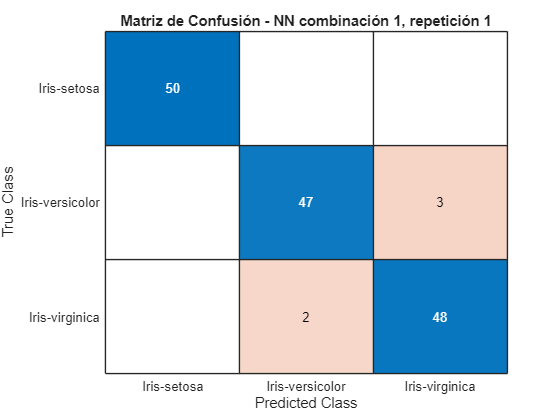

% Selecciona la combinación deseada
selectedFolds = allFoldsNN{1, 1};

real_all = [];
pred_all = [];
for i = 1:length(selectedFolds)
    fold = selectedFolds{i};
    real_all = [real_all; fold.Real];
    pred_all = [pred_all; fold.Prediccion];
end

real_all_str = string(real_all);
pred_all_str = string(pred_all);

figure;
[CM, ORDERCM] = confusionmat(real_all_str, pred_all_str);
confusionchart(real_all_str, pred_all_str);
title(sprintf('Matriz de Confusión - NN combinación %d, repetición %d', 1, 1));

% === COMPARACIÓN ENTRE REDES NEURONALES ===

rep = 1;  % Seleccionamos una repetición (puedes repetir con rep=2 y rep=3)
numCombinaciones = size(metricsFoldsNN.Accuracy, 2);  % modelos
numFolds = size(metricsFoldsNN.Accuracy, 1);  % normalmente 10

accuracy_todos = [];
grupos = [];

for modelIdx = 1:numCombinaciones
    acc_folds = metricsFoldsNN.Accuracy(:, modelIdx, rep);
    
    accuracy_todos = [accuracy_todos; acc_folds];
    grupos = [grupos; repmat(modelIdx, numFolds, 1)];
end

% Kruskal-Wallis
[p_kw_nn, tabla_kw_nn, stats_kw_nn] = kruskalwallis(accuracy_todos, grupos, 'off');
fprintf("Kruskal-Wallis entre redes neuronales (rep %d): p = %.4e\n", rep, p_kw_nn);

Kruskal-Wallis entre redes neuronales (rep 1): p = 5.9346e-01



if p_kw_nn < 0.05
    fprintf("Diferencias significativas entre redes neuronales detectadas. Realizando comparaciones múltiples:\n");
    cNN = multcompare(stats_kw_nn, 'CType', 'bonferroni');
else
    fprintf("No se detectaron diferencias significativas entre los modelos.\n");
end

No se detectaron diferencias significativas entre los modelos.


Boxplot entre NNs

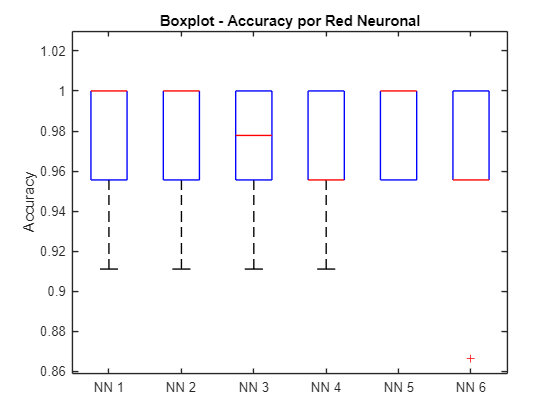

rep = 1;  % Repetición que quieras visualizar
numModelos = size(metricsFoldsNN.Accuracy, 2);

% Obtener las accuracies por fold de cada modelo
accMatrix = squeeze(metricsFoldsNN.Accuracy(:, :, rep));  % (folds × modelos)
f1Matrix  = squeeze(metricsFoldsNN.F1Score(:, :, rep));   % (folds × modelos)

% Etiquetas para los modelos
labels = strings(1, numModelos);
for i = 1:numModelos
    labels(i) = sprintf('NN %d', i);
end

% Boxplot de Accuracy
figure;
boxplot(accMatrix, 'Labels', labels);
ylabel('Accuracy');
title('Boxplot - Accuracy por Red Neuronal');

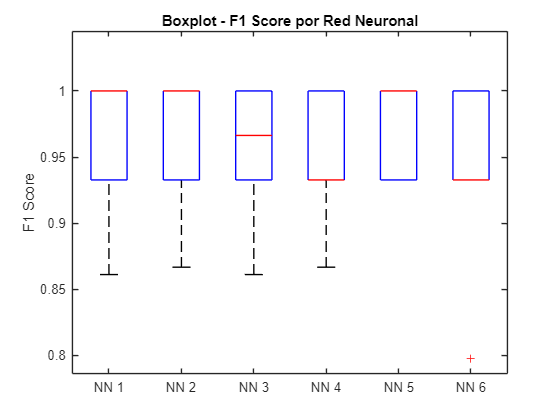


% Boxplot de F1Score
figure;
boxplot(f1Matrix, 'Labels', labels);
ylabel('F1 Score');
title('Boxplot - F1 Score por Red Neuronal');

Guardar mejor modelo en disco

% Encontrar el índice del modelo más sencillo
idx_sencillo = find(combinaciones(:,1) == 5 & combinaciones(:,2) == 1);  % neuronas = 5, algoritmo = trainscg

mejorNN = nnModels{1, idx_sencillo, rep};  % rep = 1

modeloFinal.red = mejorNN;
modeloFinal.mediaTrain = mn;     % media usada para normalizar durante el entrenamiento
modeloFinal.stdTrain = sd;       % desviación típica
modeloFinal.clases = clasesUnicas;

% guardarlo en disco
save('modeloFinal_NN.mat', 'modeloFinal');

Cargar mejor modelo

load('modeloFinal_NN.mat');

% Extraer sus métricas por fold
accuracy_bestNN = metricsFoldsNN.Accuracy(:, idx_sencillo, rep);

accuracy_total = [accuracy_Tree; accuracy_LDA; accuracy_QDA; accuracy_SVM1; accuracy_bestNN];
grupos_total = [repmat("DecisionTree", 10, 1);
                repmat("LDA", 10, 1);
                repmat("QDA", 10, 1);
                repmat("SVM", 10, 1);
                repmat("Simple_NN", 10, 1)];

[p_kw_all, tabla_kw_all, stats_kw_all] = kruskalwallis(accuracy_total, grupos_total, 'off');
fprintf("\nKruskal-Wallis (Simple NN vs modelos clásicos): p = %.4e\n", p_kw_all);


Kruskal-Wallis (Simple NN vs modelos clásicos): p = 8.1878e-01



if p_kw_all < 0.05
    fprintf("Diferencias significativas detectadas. Comparaciones múltiples:\n");
    cAll = multcompare(stats_kw_all, 'CType', 'bonferroni');
else
    fprintf("No se detectaron diferencias significativas entre los modelos.\n");
end

No se detectaron diferencias significativas entre los modelos.


Boxplot entre mejor NN, SVM, DecisionTree, QDA y LDA

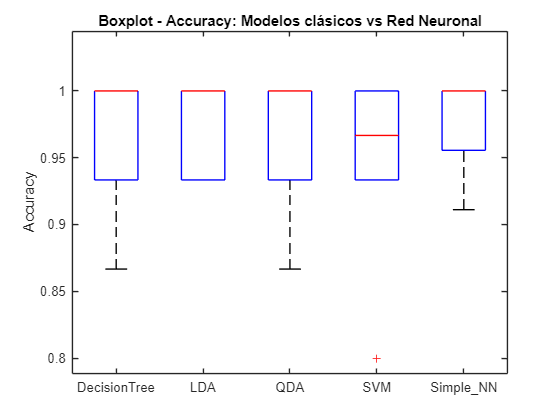

accuracy_total = [accuracy_Tree; accuracy_LDA; accuracy_QDA; accuracy_SVM1; accuracy_bestNN];
grupos_total = [repmat("DecisionTree", 10, 1);
                repmat("LDA", 10, 1);
                repmat("QDA", 10, 1);
                repmat("SVM", 10, 1);
                repmat("Simple_NN", 10, 1)];

figure;
boxplot(accuracy_total, grupos_total);
ylabel('Accuracy');
title('Boxplot - Accuracy: Modelos clásicos vs Red Neuronal');